# PRÁCTICA 3 - SESIÓN 1 

# 1. EXTRACCIÓN DE REGIONES

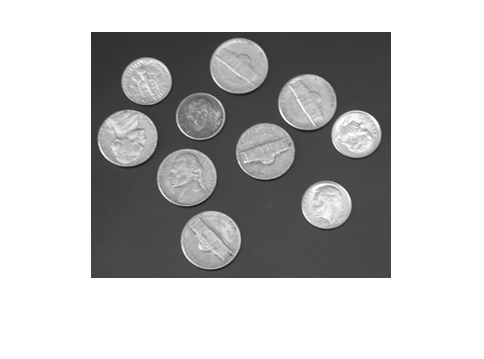

% Cargar una imagen de ejemplo en escala de grises
coins = imread('coins.png');

% Mostrar la imagen original
figure;
imshow(coins)

## Transformamos a binario (blanco y negro)

% Puedes usar im2bw (más antiguo) o imbinarize (más moderno), hacen lo mismo
BW = im2bw(coins); % transforma la imagen a binaria (BW)
%BW = imbinarize(coins);

% Etiquetar los objetos conectados en la imagen binaria
% label: imagen con las etiquetas asignadas a cada objeto (1, 2, 3, ...)
% num: número total de objetos detectados
[label,num] = bwlabel(BW)

label =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

num = 15

% Obtener el perímetro (bordes) de los objetos binarios
% La conectividad 4 considera vecinos en direcciones vertical y horizontal
perimetro = bwperim(BW,4)

perimetro = 246×300 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

## Cargamos imagen y visualizamos

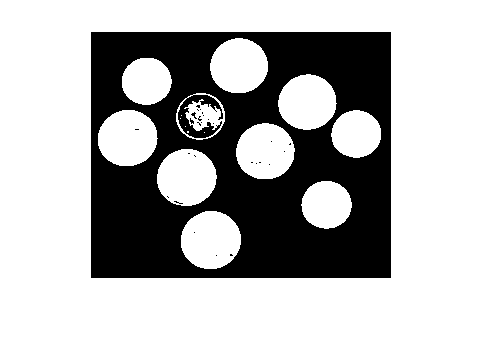

% Mostrar la imagen binaria en bn
figure;
imshow(BW) 

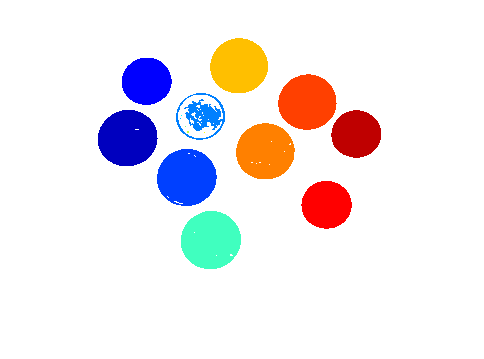

% Mostrar la imagen etiquetada con un mapa de colores (Convierte etiquetas a colores para visualizar de forma clara las diferentes regiones de la imagen)
figure;
label1= label2rgb(label);
imshow(label1)

## Creamos nueva imagen porque no hay objetos segmentados correctamente

Este proceso sirve para **mejorar la segmentación** de los objetos en la imagen cuando no han sido bien detectados con la binarización básica. A veces, al binarizar una imagen, los objetos aparecen **con huecos internos** o **no están completamente segmentados**. Esto puede dificultar el análisis, por ejemplo, el conteo o la identificación de formas completas. La función `imfill` ayuda a **rellenar los agujeros internos** en los objetos binarios.

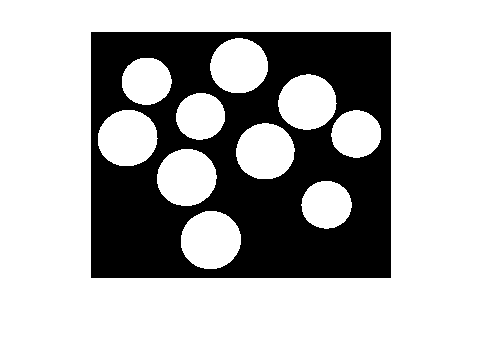

% Aplicamos imfill para rellenar huecos dentro de los objetos blancos
% 'holes' indica que se rellenan los huecos oscuros completamente rodeados por blancos
BW1 = imfill(BW, 'holes');

% Mostrar la nueva imagen binaria mejorada
figure;
imshow(BW1);

% Etiquetamos los objetos conectados en esta nueva imagen
[label2, num1] = bwlabel(BW1)

label2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

num1 = 10

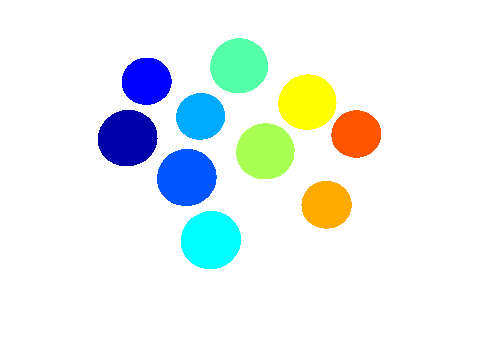

% Convertimos las etiquetas a colores para visualizar los objetos
label2_coloreada = label2rgb(label2);

% Mostramos la imagen etiquetada y coloreada
figure;
imshow(label2_coloreada);

## Calcula los bordes de los objetos con bwboundaries

Este fragmento de código usa `bwboundaries` para **calcular y visualizar los contornos** (bordes exteriores) de los objetos binarios segmentados (por ejemplo, monedas) en una imagen, incluso si están tocando o muy cerca unos de otros.

% Calcular los bordes de los objetos en la imagen binaria
% 'noholes' indica que solo se detecten contornos exteriores (no internos)
[bordes, L] = bwboundaries(BW1, 'noholes')  % Cada número en L indica a qué objeto pertenece cada píxel

bordes = 10×1 cell array
    {164×2 double}
    {137×2 double}
    {164×2 double}
    {135×2 double}
    {166×2 double}
    {159×2 double}
    {162×2 double}
    {159×2 double}
    {139×2 double}
    {136×2 double}


L =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

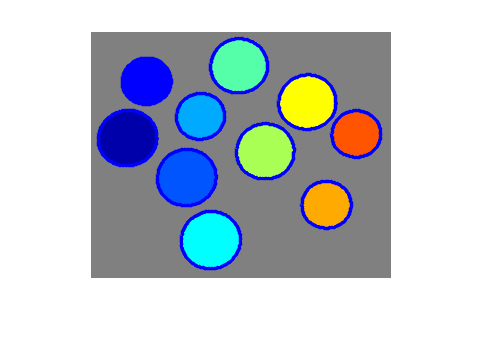

% Mostrar la imagen de etiquetas coloreadas
figure;
imshow(label2rgb(L, @jet, [.5 .5 .5])); % label2rgb colorea cada etiqueta con un color distinto usando el mapa 'jet'
                                        % fondo gris ([5. 5. 5.) = (R G B)]
hold on;  % Mantener la imagen para superponer los bordes

% Recorrer cada contorno detectado y dibujarlo
for k = 1:length(bordes)
    boundary = bordes{k};  % Extraer las coordenadas del borde k
    plot(boundary(:,2), boundary(:,1), 'b', 'LineWidth', 2);  % Dibujar en azul
end

## Calcula los bordes de los objetos con bwperim

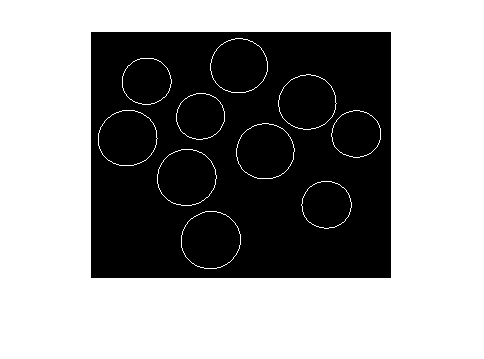

% Calcular los bordes con bwperim
bordes2 = bwperim(BW1);

% Mostrar los bordes sobre fondo negro
figure;
imshow(bordes2);

## Diferencias entre bwboundaries y bwperim

#### 1. bwboundaries

- Devuelve una celda con coordenadas (x,y) del contorno de cada objeto.

- Usa un algoritmo de seguimiento del borde (contour tracing).

- Es más robusto y preciso, especialmente en imágenes complejas.

- Maneja bien huecos internos, objetos irregulares y topologías complicadas.

- Devuelve información rica: localización punto a punto, dirección, longitud.

- Recomendado cuando necesitas precisión, análisis geométrico, o visualizar contornos detallados.

#### 2. bwperim

- Devuelve una imagen binaria con píxeles "1" donde hay borde del objeto.

- Es rápido y simple: ideal para imágenes sencillas.

- No distingue entre contornos internos o externos.

- No proporciona coordenadas ni estructura detallada.

- Útil si solo necesitas saber dónde hay borde, sin más análisis.

#### RESUMEN

- Usa bwboundaries si necesitas detalle, precisión o tienes formas complejas.

- Usa bwperim si necesitas rapidez y tu imagen es simple.

# 2. CÁLCULO DE DESCRIPTORES BÁSICOS

## Cálculo de las componentes conectadas de Bw1

Las **componentes conectadas** en una imagen binaria son **grupos de píxeles blancos (valor 1)** que están **conectados entre sí** siguiendo un cierto criterio de vecindad (por ejemplo, vecinos de 4 u 8 direcciones). Es como un "objeto" o "mancha blanca" en la imagen binaria, que está **separado de otros objetos por píxeles negros (valor 0)**.

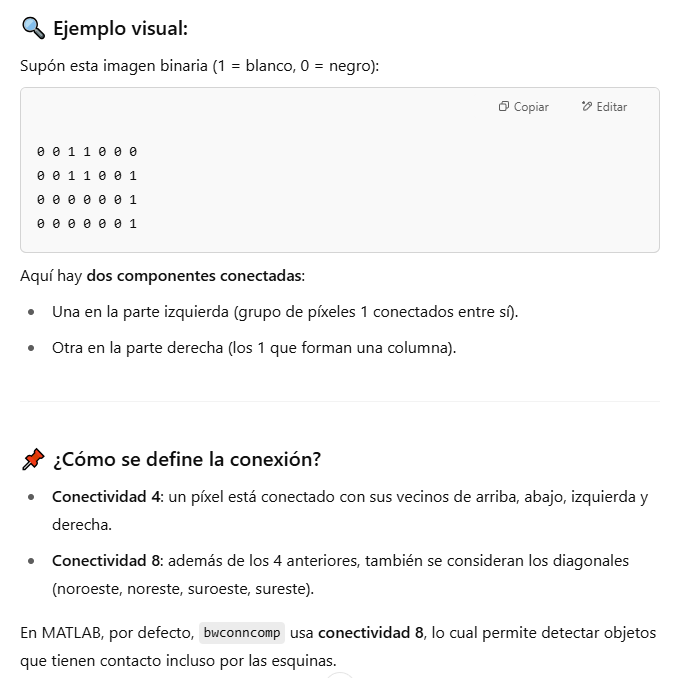

% Extraer las componentes conectadas (objetos binarios separados)
cc = bwconncomp(BW1);
% Si detecta menos de 10 monedas, puede ser que algunas estén tocando y las
% haya unido como un solo objeto, por eso obtenemos 8 monedas cuando tenemos 10

## Cálculo de los centroides de los objetos

% Calcular el centroide de cada componente conectada
S = regionprops(cc, 'Centroid')

S = 10×1 struct array with fields:
    Centroid


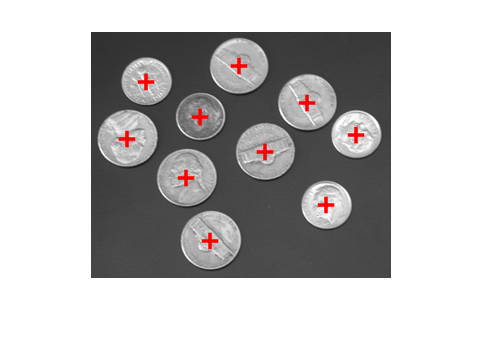

% Mostrar la imagen original y superponer los centroides
figure;
imshow(coins);
hold on;
for k = 1:length(S)
    c = S(k).Centroid;
    plot(c(1), c(2), 'r+', 'MarkerSize', 10, 'LineWidth', 2); % Marcar cada centroide con una cruz roja
end

## Cálculo propiedades morfológicas de los objetos

% Calcular perímetro de los objetos
perimetro = regionprops(BW1, 'Perimeter')

perimetro = 10×1 struct array with fields:
    Perimeter


% Longitud del eje mayor de la elipse ajustada
long_eje_mayor = regionprops(BW1, 'MajorAxisLength')

long_eje_mayor = 10×1 struct array with fields:
    MajorAxisLength


% Longitud del eje menor de la elipse ajustada
long_eje_menor = regionprops(BW1, 'MinorAxisLength')

long_eje_menor = 10×1 struct array with fields:
    MinorAxisLength


% Excentricidad (cercanía a forma elíptica o circular)
excen = regionprops(BW1, 'Eccentricity')

excen = 10×1 struct array with fields:
    Eccentricity


% Diámetro equivalente (diámetro de un círculo con la misma área)
diameter = regionprops(BW1, 'EquivDiameter')

diameter = 10×1 struct array with fields:
    EquivDiameter


% Rectángulo que encierra cada objeto
rect = regionprops(BW1, 'BoundingBox')

rect = 10×1 struct array with fields:
    BoundingBox


% Área de cada objeto
area = regionprops(BW1, 'Area')

area = 10×1 struct array with fields:
    Area


% Lista de píxeles de cada objeto (x,y)
pixeles = regionprops(BW1, 'PixelList')

pixeles = 10×1 struct array with fields:
    PixelList


% Número de Euler = (nº de objetos) - (nº de huecos internos)
euler = regionprops(BW1, 'EulerNumber')

euler = 10×1 struct array with fields:
    EulerNumber


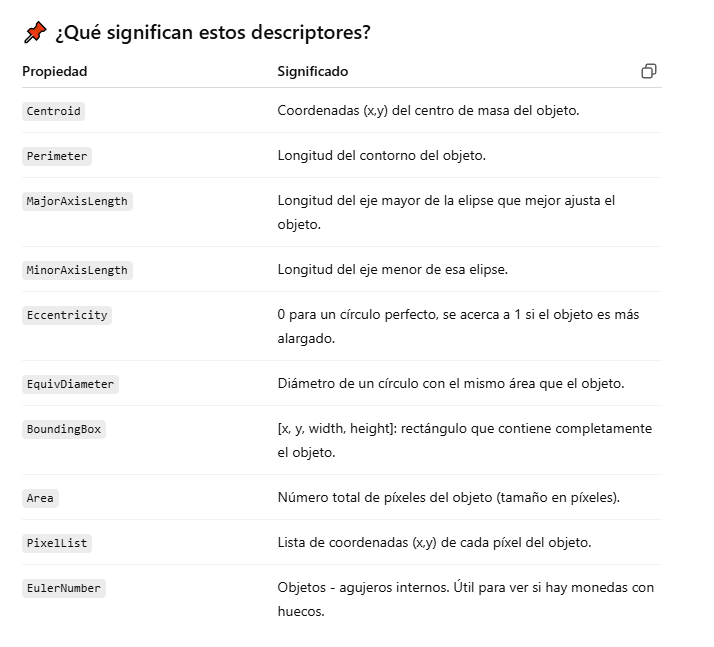

# 3. DESCRIPTORES BÁSICOS SOBRE IMAGEN MÉDICA

Vamos a aplicar los conceptos anteriores sobre algunas imágenes médicas de ejemplo. En concreto, vamos a analizar dos retinografías. 

## Visualización imagen original (papila + exudados)

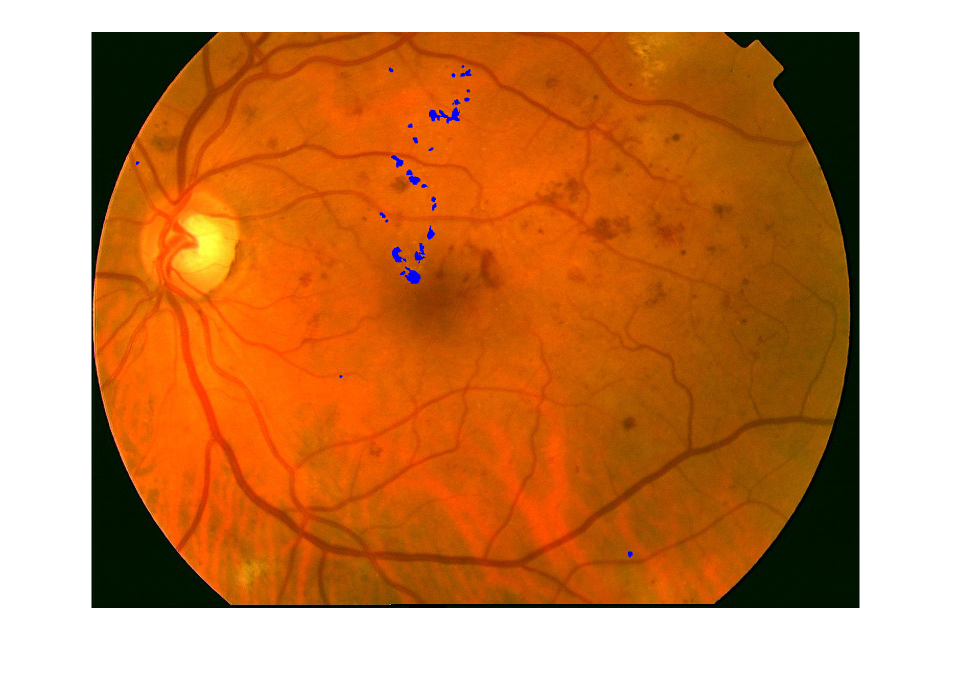

exudados_jpg = imread("exudados22.jpg");
figure;
imshow(exudados_jpg)

## Representacion de exudados segmentados

Aquí, `im_out2` es una imagen binaria donde los **exudados** (lesiones brillantes en la retina) están marcados como blancos (1) y el resto como negro (0).

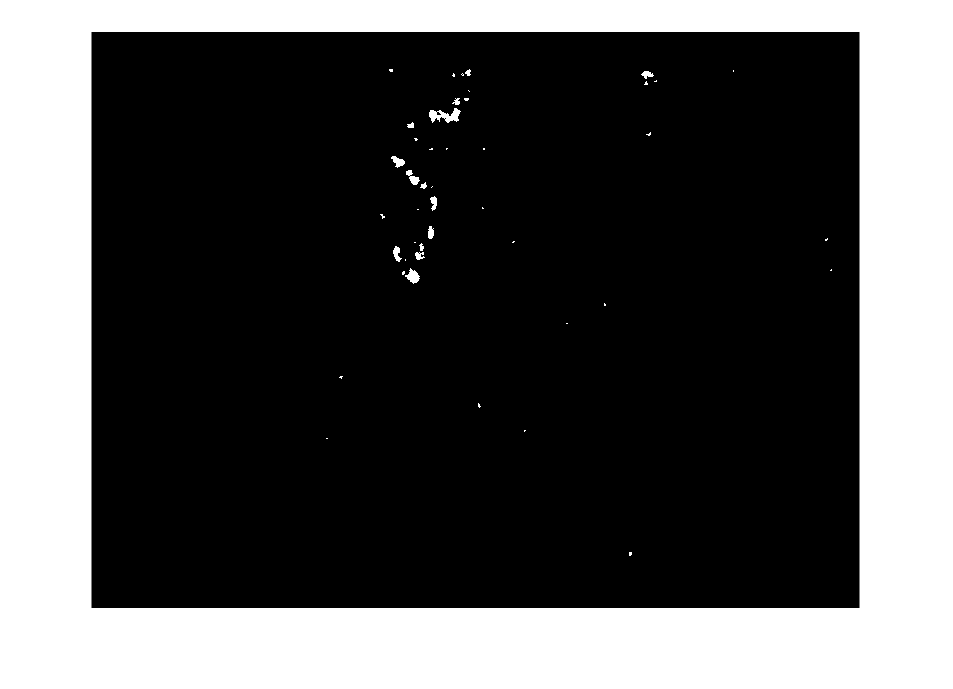

% Cargar la imagen binaria segmentada de exudados
exudados = load('EX2_exudados22.mat');  % Contiene una variable llamada im_out2
figure;
imshow(exudados.im_out2);

## Representación de la papila óptica segmentada

La **papila óptica** es la zona por donde entra el nervio óptico. Es importante segmentarla para **evitar confusiones** con exudados debido a su brillo.

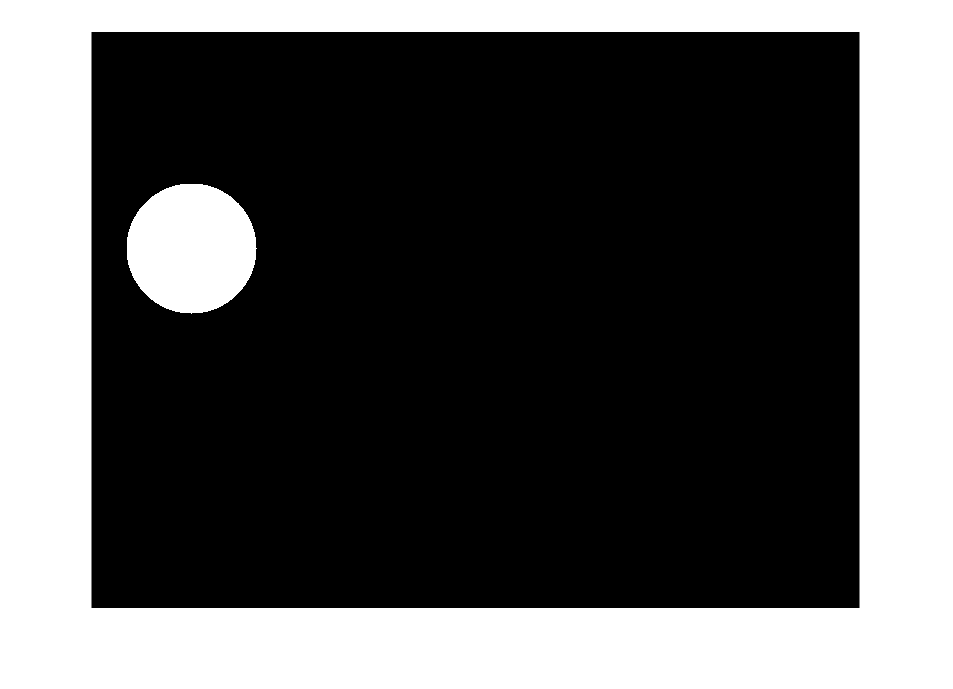

% Cargar la imagen binaria segmentada de la papila óptica
load('papila_exudados22.mat');  % Contiene la variable 'papila'
figure;
imshow(papila);

## Cálculo de las componentes conectadas

El objetivo principal es **identificar y aislar** las regiones de la imagen que corresponden a **objetos o estructuras individuales** dentro de la imagen segmentada.

% Identificar regiones conectadas en la segmentación de la papila
cc_papila = bwconncomp(papila) % Debería ser 1, porque solo hay una papila

cc_papila = struct with fields:
    Connectivity: 8
       ImageSize: [576 768]
      NumObjects: 1
    PixelIdxList: {[13259×1 double]}


% Identificar regiones conectadas en los exudados
cc_im_out2 = bwconncomp(exudados.im_out2) % Normalmente se detectan muchas pequeñas lesiones (por ejemplo, 44)

cc_im_out2 = struct with fields:
    Connectivity: 8
       ImageSize: [576 768]
      NumObjects: 44
    PixelIdxList: {1×44 cell}


## Cálculo de propiedades sobre la papila segmentada

% Calcular el centroide de la papila
S1 = regionprops(cc_papila, 'Centroid')

S1 = struct with fields:
    Centroid: [101.0213 216.9807]


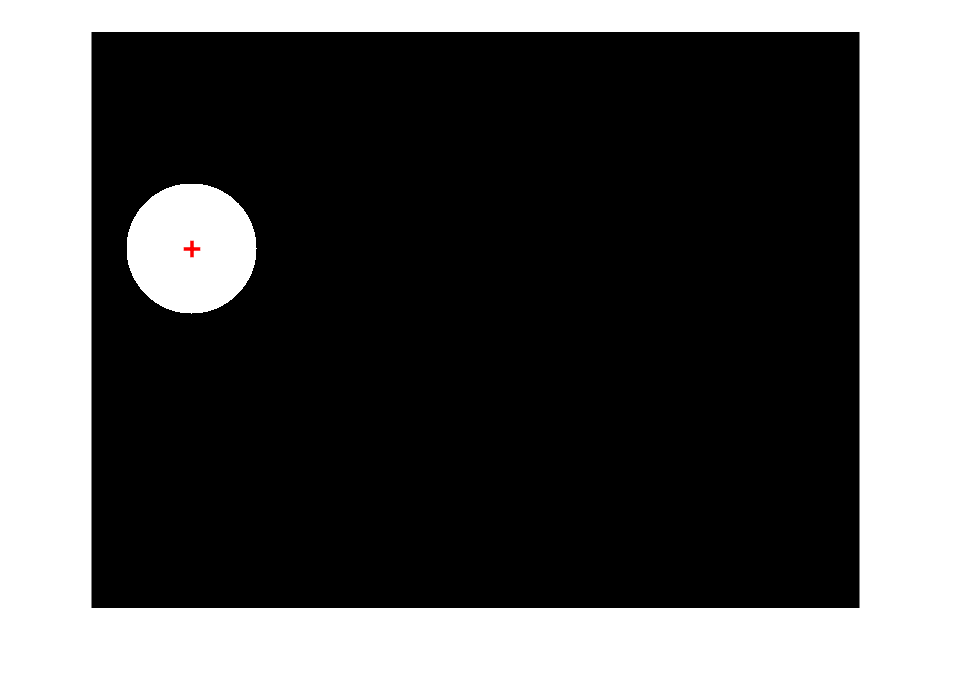

% Mostrar la imagen original y superponer el centroide
figure;
imshow(papila);
hold on;
for k1 = 1:length(S1)
    c1 = S1(k1).Centroid;
    plot(c1(1), c1(2), 'r+', 'MarkerSize', 10, 'LineWidth', 2); % Marcar el centroide con una cruz roja
end

% Calcular perímetro de la papila
perimetro_papila = regionprops(papila, 'Perimeter')

perimetro_papila = struct with fields:
    Perimeter: 406.1010


% Longitud del eje mayor de la papila
long_eje_mayor_papila = regionprops(papila, 'MajorAxisLength')

long_eje_mayor_papila = struct with fields:
    MajorAxisLength: 129.9420


% Longitud del eje menor de la papila
long_eje_menor_papila = regionprops(papila, 'MinorAxisLength')

long_eje_menor_papila = struct with fields:
    MinorAxisLength: 129.9300


% Excentricidad (cercanía a forma elíptica o circular)
excen_papila = regionprops(papila, 'Eccentricity')

excen_papila = struct with fields:
    Eccentricity: 0.0136


% Diámetro equivalente (diámetro de un círculo con la misma área)
diameter_papila = regionprops(papila, 'EquivDiameter')

diameter_papila = struct with fields:
    EquivDiameter: 129.9303


% Rectángulo que encierra a la papila
rect_papila = regionprops(papila, 'BoundingBox')

rect_papila = struct with fields:
    BoundingBox: [36.5000 152.5000 130 130]


% Área de la papila
area_papila = regionprops(papila, 'Area')

area_papila = struct with fields:
    Area: 13259


% Lista de píxeles de la papila (x,y)
pixeles_papila = regionprops(papila, 'PixelList')

pixeles_papila = struct with fields:
    PixelList: [13259×2 double]


% Número de Euler = (nº de objetos) - (nº de huecos internos)
euler_papila = regionprops(papila, 'EulerNumber')

euler_papila = struct with fields:
    EulerNumber: 1


## **Cálculo de la intensidad media de la papila**

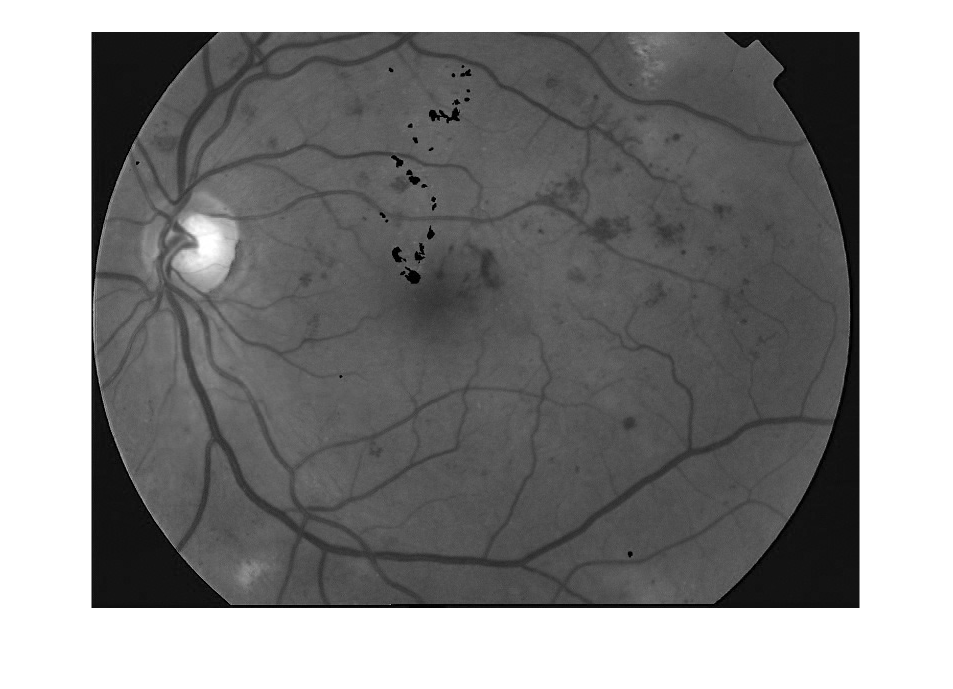

im = imread("exudados22.jpg");

% Extraer el canal verde de la imagen original
canal_verde = im(:,:,2); % El canal verde suele ofrecer más contraste en imágenes de retina y es más útil para el análisis de estructuras vasculares y lesiones

% Representamos el canal verde
figure()
imshow(canal_verde)

% Calculamos la intensidad media solo dentro de la papila, a partir de su segmentación binaria
intensidad_media = regionprops(cc_papila, canal_verde, 'MeanIntensity')

intensidad_media = struct with fields:
    MeanIntensity: 131.3594
